# Solving the 1st Order Linear ODEs using Runge Kutta 3rd Order Method

Ordinary Differential Equations are the common types of equations in engineering problems. Some of them are very hard to solve, and basically their common and private answer are not necessary. Thus, the numerical methods are very useful in these cases. One of the numerical methods to solve the 1st order linear ODEs is Runge Kutta 3rd Order.

Each 1st order ODE can be showed as a function of dependent variables. for example:


$$\frac{\mathrm{dy}}{\mathrm{dx}}=y^2 +3\sin \left(x\right)=f\left(x,y\right)$$


The iterative method is showed as follows:

$y_{i+1} =y_i +\frac{\left(h\times \left(k_1 +2k_2 +2k_3 +k_4 \right)\right)}{4}$ , which h represent the step length. The $k_1 \;,k_2 ,k_3 \;,k_4$ parameters are calculated using these formulas:


$$k_1 =f\left(x_i ,y_i \right)\;,k_2 =f\left(x_i +\frac{h}{2},y_i +k_1 \frac{h}{2}\right),k_3 =f\left(x_i +h,y_i -k_1 h+2k_2 h\right)$$


### Part1: Input data

clear, clc
syms x
syms y
f = input('Enter the equation of f(x,y): ');    
% if your function doesn't have 'y' or 'x' variable, insert '0*y' or '*x' in the end of function equation
X = input('Enter the vector of xi(first element of vector is x0): ');
Y = ones(1,length(X));  % initial value of yi vector
Y(1,1) = input('Enter the value of y0: ');     % Value of y0

y0 is the initial guess!

h = input('Enter the value of step: ');          % Value of h(step size)
n = length(X);

### Part2: ODE Calculation

for i = 1:(n-1)     % Iteration number
       p1 = subs(f,x,X(1,i));                   %Calling f(x,y) & calculate k1
       k1 = subs(p1,y,Y(1,i));
       p2 = subs(f,x,(X(1,i)+(h/2)));           %Calling f(x,y) & calculate k2
       k2 = subs(p2,y,(Y(1,i) + (k1*h/2)));     
       p3 = subs(f,x,(X(1,i)+h));               %Calling f(x,y) & calculate k3
       k3 = subs(p3,y,(Y(1,i)-(k1*h)+(2*k2*h)));    
       Y(1,i+1) = Y(1,i) + (h/6)*(k1+4*k2+k3);  % Calculating the value of y(i+1)
end
Xi = X';
Yi = Y';
i = (0:(n-1))';

### Part3: Results

disp('The results of calculation are:');

The results of calculation are:


result = table(i,Xi,Yi);
disp(result);

    i     Xi      Yi  
    __    __    ______

     0     0         0
     1     1    1.7129
     2     2    6.9166
     3     3    14.972
     4     4    26.296
     5     5    43.816
     6     6     72.12
     7     7    115.07
     8     8     174.1
     9     9    248.74
    10    10    338.85



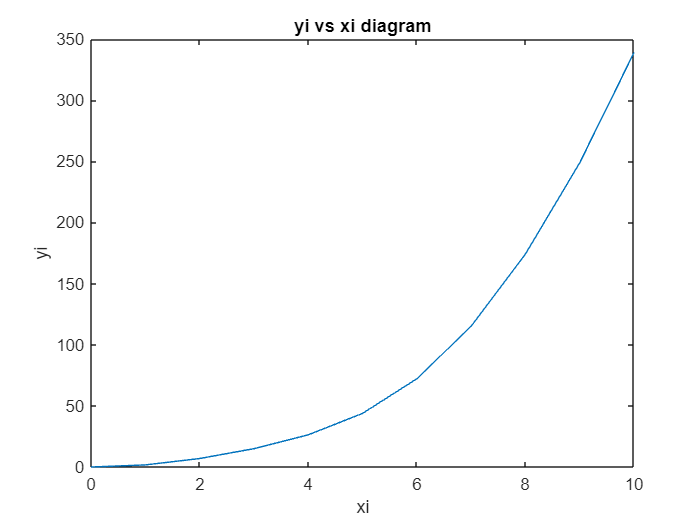

plot(X,Y)
xlabel('xi')
ylabel('yi')
title('yi vs xi diagram')